# Potential Flow Solver

This matlab program can calculate the velocity distribution and the lift coefficient of airfoils. It does so by using thin airfoil theory, and using potential flow theory. The results are thus only valid for thin airfoils at incompressible air conditions, for small angles of attack.

The camberline input is in its local coordinate system, later this will be adjusted with the given angle of attack. It must be given as a function of x over the chord length. The quiver ratio is the ratio between the amount of grid cells and the amount of quivers. Uinf is the farfield velocity.


Nnodes = 30; %[-]
Lpanel = 2; %[m]
AoA    = 5; %[deg]
Uinf   = [10;0]; %[m/s]
rho    = 1.225; %for steady method this is a dummy value
z      = @(x_c) 0.1*sin(pi*x_c); %[m]

step   = 0.02; %[m] grid size step
qr     = 5; %[-] quiver ratio



x      = linspace(0,Lpanel/cosd(AoA),Nnodes);
nodes  = [x;z(x/Lpanel)];

%transform the nodes with the given angle of attack
nodes =  [cosd(-AoA),-sind(-AoA);sind(-AoA),cosd(-AoA)]*nodes;


model  = PanelMethod(nodes,Uinf,rho);

xdom = -Lpanel:step:2*Lpanel;
zdom = -Lpanel:step:Lpanel;
offset = [0;0];

sresults = model.solveSteady();

## Steady Flow

 
fprintf('Cl = %f',sresults.Cl);

Cl = 1.094088

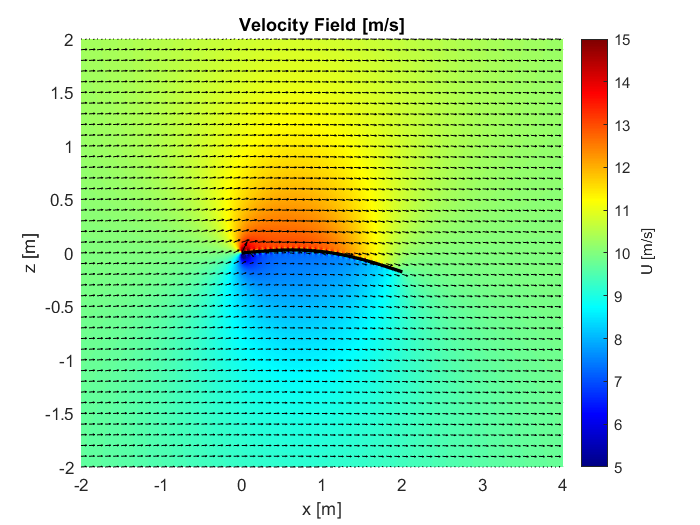


[U,W] = model.getVelocityField(xdom,zdom,model.xg,sresults.gammas);
[X,Z] = meshgrid(xdom,zdom);

clab = " U [m/s]";
clims = [Uinf(1)*0.5,Uinf(1)*1.5];
model.plotField(X,Z,U,clab,offset,clims);
quiver(X(1:qr:end,1:qr:end),Z(1:qr:end,1:qr:end), ...
       U(1:qr:end,1:qr:end)',W(1:qr:end,1:qr:end)', 'k');
title("Velocity Field [m/s]");
xlim([min(xdom),max(xdom)]);
ylim([min(zdom),max(zdom)]);

## Unsteady flow

The lift of the airfoil is in reality not immediatly equal to the steady state lift. This is because at start-up, a vortex is created at the trailing edge of the airfoil, that limits the lift. Below the development of Cl over time is shown. You can also choose to save a video of the starting vortex, which will be saved in this directory.

tend = 1;
dt   = tend/100;
videoName = "StartingVortex"+".avi";

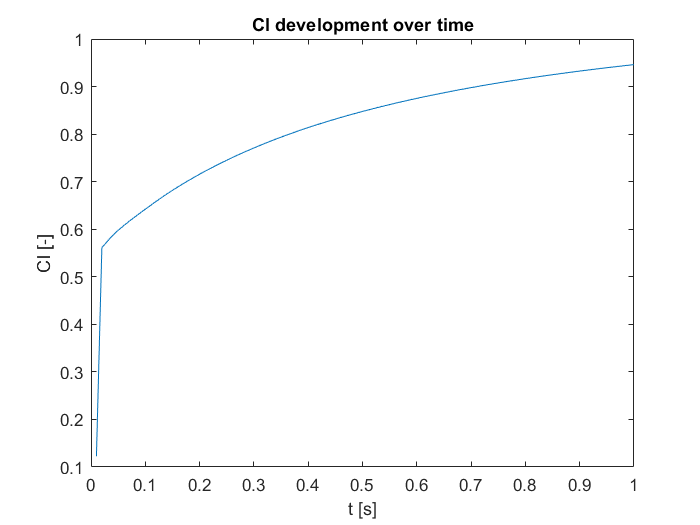


  saveVideo = true;

theta    = @(t) 0;
thetadot = @(t) 0;

results = model.solveUnsteady(tend,dt,theta,thetadot);

figure();
plot(dt:dt:tend,results.Cls);
title("Cl development over time");
xlabel("t [s]")
ylabel("Cl [-]")
figure();

if saveVideo
    model.saveVortex(dt,Lpanel,results,videoName);
end